# Pogetto Robust Control Natale Marco (a.a. 24/25)         🇵🇸  07/10

Per il progetto è stato scelto il problema benchmark **IFAC #90-10 "Regulation of a ship's heading"**, in cui viene chiesto di progettare un controllore per la regolazione dell'angolo di rotta di una nave. 

Nel seguente progetto vengono proposte due soluzioni di controllori $H_\infty$ per il sistema incerto in esame, utilizzando il comando `hinfsyn`, del Robust Control Toolbox, con conseguente *μ*-analysis per stimare la stabilità robusta del sistema incerto. 

Sono state considerate le seguenti specifiche: 

- Nessuna sovraelongazione nella risposta y del sistema;

- Stabilità robusta del sistema incerto;

Sono state ignorate le richieste *(b)* e *(c)* originariamente proposte nel problema benchmark IFAC.

# 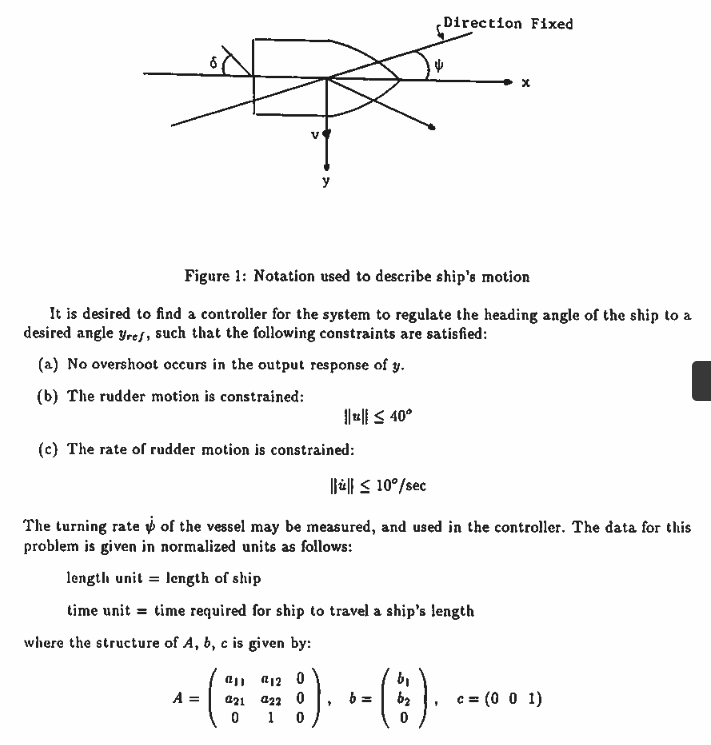

### Modello e Incertezze

Il problema propone 5 modelli, dei quali 3 sono stati utilizzati per lo sviluppo del progetto (*Tanker#1, Tanker#2, Tanker#3*), scegliendo il terzo modello come nominale e considerando gli altri due come bounds degli intervalli per i parametri incerti. Sono stati scelti 3 parametri incerti dei 6 totali proposti, i quali sono: $a_{11}$, $a_{21}$ e $b_1$.

Le equazioni per il modello linearizzato in spazio di stato sono: 


$$ \;\;\;\; \begin{array}{ccl} \dot{x_1} & = & a_{11_u}x_1 + a_{12}x_2 + b_{1_u}u \\ 
\dot{x_2} & = &  a_{21_u}x_1 + a_{22}x_2 + b_{2}u \\ 
\dot{x_3} &=& x_2 \\ 
y &=& x_3  \end{array} $$


dove:

- $a_{{11}_u }$ è il parametro incerto $a_{11} \in \left\lbrack -0\ldotp 597,-0\ldotp 298\right\rbrack$

- $a_{{21}_u }$ è il parametro incerto $a_{21} \in \left\lbrack -4\ldotp 37,-3\ldotp 651\right\rbrack$

- $b_{1_u }$ è il parametro incerto $b_1 \in \left\lbrack 0\ldotp 097,0\ldotp 116\right\rbrack$

#### Definizione Incertezze e Sistema 

% Considero Tanker 3 come sistema nominale 
clc; close all;

% Incertezze considerate: a_11 a_21 b1_u 
a11_nom = -0.454;
a21_nom = -4.005;
b1_nom = 0.103 ; 

a11_u = ureal('a11_u', a11_nom, 'Range', [-0.597, -0.298]);

a21_u = ureal('a21_u', a21_nom, 'Range', [-4.37, -3.651]);
b1_u = ureal('b1_u', b1_nom, 'Range', [0.097, 0.116]);

a12 = -0.433;
a22 = -0.807;
b2 = -0.807;


### Sistema


A = [a11_u a12 0; a21_u a22 0; 0 1 0];

B = [b1_u b2 0]';

C = [0 0 1];
D = 0;

% modello di spazio di stato incerto
G_ss = ss(A, B, C, D);
disp("Sistema Nominale pazio di Stato:  ")

Sistema Nominale pazio di Stato:  


G0_ss = G_ss.NominalValue


G0_ss =
 
  A = 
           x1      x2      x3
   x1  -0.454  -0.433       0
   x2  -4.005  -0.807       0
   x3       0       1       0
 
  B = 
           u1
   x1   0.103
   x2  -0.807
   x3       0
 
  C = 
       x1  x2  x3
   y1   0   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


G_ss;

% f.d.t.
G_tf = tf(G_ss)


G_tf =
 
      -0.807 s - 0.7789
  -------------------------
  s^3 + 1.261 s^2 - 1.368 s
 
Continuous-time transfer function.
Model Properties


G0_tf = minreal(tf(G0_ss));
disp("I poli del sistema open loop sono: ")

I poli del sistema open loop sono: 


disp(pole(G_tf))

         0
   -1.9592
    0.6982



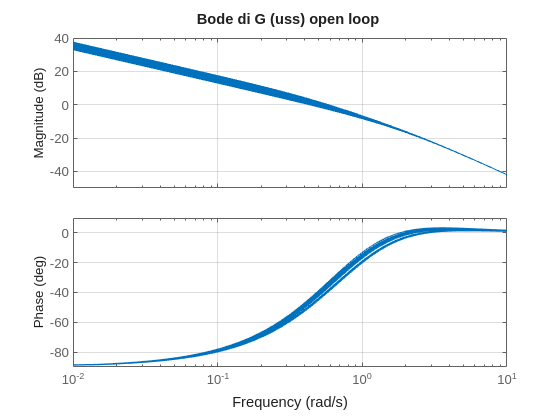

bode(G_ss)
grid on
title("Bode di G (uss) open loop ")

### Forma TITO P1

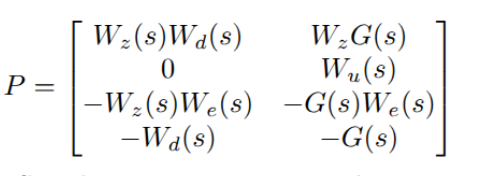

La forma TITO *P1 *è stata ricavata a mano scegliendo i pesi:

- *Wz *per portare l'uscita di interesse y ( = z ) a zero 

- *Wu *per cercare di limitare lo sforzo di controllo 

- *Wd *per reiettare i disturbi in bassa frequenza

- *We *per limitare l'errore y-r 

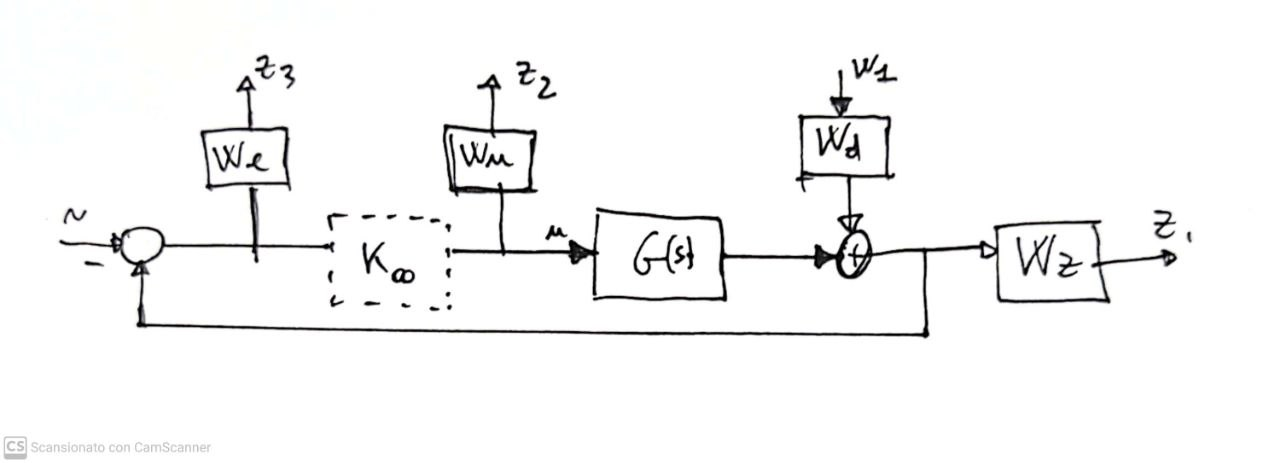

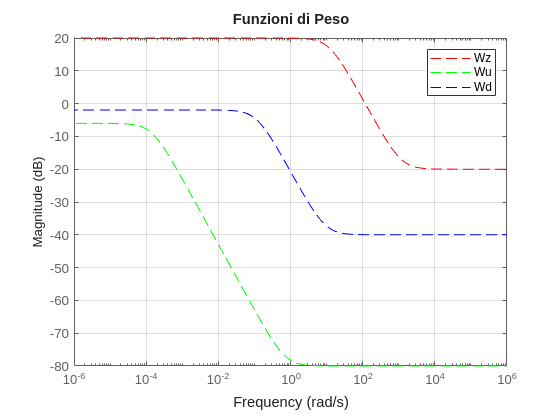


% Wu = makeweight(Wu_static, [10 Wu_static/10], Wu_static/1000); 
% Wz = makeweight(20, 0.01, 0.01); VERI OG
% Wu = makeweight(1, [10 .1], Wu_static/1000); 
% Wz = makeweight(50 ,[0.05 1],0.01);
% Wd = makeweight(50, [1 0.01], 0.001);
% We = makeweight(10, [1 1], 0);

Wu_static = 1 / (40 * pi / 180);
Wz = makeweight(10, [12 7], .1);
Wu = makeweight(.5, [0.005 Wu_static/100], 0.0001);
Wd = makeweight(0.8, [0.2 0.4], 0.01);
We = makeweight(1, [1 0.5], 0.1); % PESI PER OVERSHOOT 1.4 % 

% Wn = makeweight(.1, [1,1], 10); 

% PLOT PESI 
bw1 = bodeplot(Wz,'r--', Wu, 'g--', Wd,'b--');
bw1.PhaseVisible = "off";
bw1.Title.String = "Funzioni di Peso";
bw1.Responses(1).Name = "Wz ";
bw1.Responses(2).Name = "Wu";
bw1.Responses(3).Name = "Wd";
bw1.LegendVisible = "on";
grid on


P = [Wz*Wd Wz*G0_tf; 
    0 Wu;
    -Wd*We -G0_tf*We;
    -Wd -G0_tf]; % P per errore e 

P = minreal(P);

10 states removed.


## CONTROLLORE $H_\infty$ (1)

Viene calcolato il controllore `Kinf `tramite l'apposito comando `hinfsyn` e si costruiscono il ciclo chiuso incerto e nominale


[Kinf, ~, gamInf]= hinfsyn(P, 1, 1);
gamInf

gamInf = 0.0161

Kinf=minreal(Kinf);

1 state removed.


disp("Il controllore Kinf risultante: ")

Il controllore Kinf risultante: 


(ss(Kinf))


ans =
 
  A = 
               x1          x2          x3          x4          x5          x6
   x1  -9.136e+04   5.406e+05  -4.296e+05  -3.294e+05   1.129e+07   3.653e+05
   x2        -155       726.1      -531.5      -507.8   1.479e+04       496.3
   x3       194.1       -1151       913.4       702.1  -2.403e+04      -777.7
   x4       38.71      -229.5       191.2       129.7       -4922        -155
   x5      -9.289       55.08       -43.8      -33.52        1150       37.21
   x6   -2.03e+04   1.204e+05  -9.572e+04  -7.327e+04   2.514e+06   8.133e+04
 
  B = 
           u1
   x1    4029
   x2   -4682
   x3   37.75
   x4  -43.09
   x5   3.544
   x6    7258
 
  C = 
               x1          x2          x3          x4          x5          x6
   y1  -4.826e+04   2.855e+05  -2.269e+05   -1.74e+05   5.961e+06   1.929e+05
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



CL = minreal(feedback(G_ss * Kinf, 1));
CL0 = CL.NominalValue;


Si procede con la **risposta al gradino **e il calcolo della **sovraelongazione** per `CL0`, il sistema a ciclo chiuso nominale con il controllore `Kinf.`

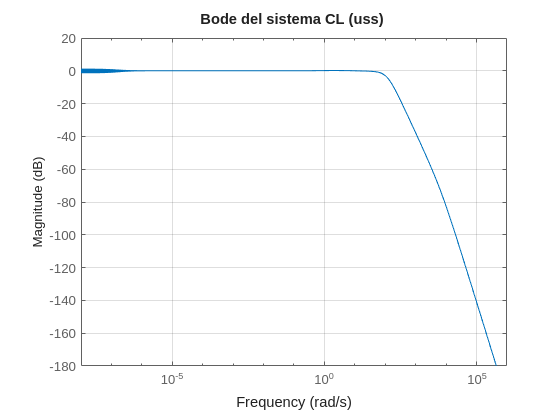

close all

bodemag(CL)
grid on
title("Bode del sistema CL (uss) ")

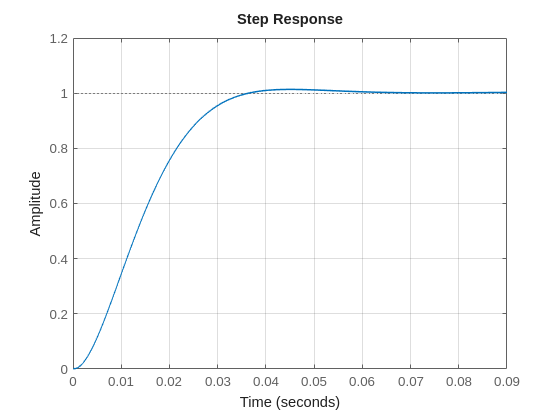


step(CL)
grid on



tfin=50;
[y_step, ~] = step(CL0, tfin);

% Calcolo overhsoot
overshoot_nom = (max(y_step) - y_step(end)) / y_step(end) * 100; 
fprintf('Overshoot nominale (%%) = %.2f\n', overshoot_nom); % Nominale overshoot

Overshoot nominale (%) = 1.46


Risposta ad una sinusoide 

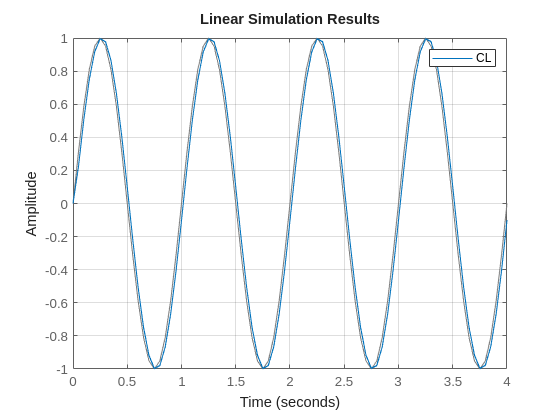


% [u,t] = gensig("sine", 20, 10, 0.05);
[u,t] = gensig("sine",1,4,0.05);
lsim(CL,u,t)
legend
grid on

Dal grafico della risposta a gradino del sistema incerto si possono dedurre due cose:

- il sistema incerto per i sample che il comando `step()` ha casualmente scelto nel range di incertezze, il sistema incerto risulta stabile;

- il sistema presenta dinamiche molto veloci, in qanto si porta a regime in meno di 0.1 *s*

Inoltre, dal clcolo effettuato, si ottiene una **sovraelongazione percentuale **dell' **1.46 % ,** che è il miglior risultato ottenuto con la variazione dei pesi a discapito di un grande sforzo di controllo. 

### Margini di stabilità robusta

Si ottengono i margini di stabilità robusta attraverso il comando `robstab()`

opts = robOptions('VaryFrequency','on','Display','on');
[stabmarg,wcu,info] = robstab(CL, opts);

Computing bounds... Points completed: 67/67
Computing peak...  Percent completed: 100/100
System is robustly stable for the modeled uncertainty.
 -- It can tolerate up to 271% of the modeled uncertainty.
 -- There is a destabilizing perturbation amounting to 271% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 114 rad/seconds.


disp(stabmarg)

           LowerBound: 2.7068
           UpperBound: 2.7130
    CriticalFrequency: 113.8553



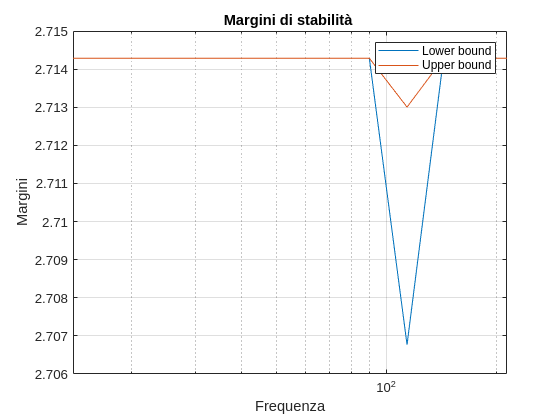


figure
semilogx(info.Frequency,info.Bounds)
title('Margini di stabilità ')
grid on
ylabel('Margini')
xlabel('Frequenza')
legend('Lower bound','Upper bound')
xlim([stabmarg.CriticalFrequency-100 stabmarg.CriticalFrequency+100])

Dall'output si deduce che il sistema è in grado di tollerare fino al 271% delle incertezze modellate (*Lower Bound e Upper Bound*), e presenta un'instabilità alla frequenza critica di 114 rad/s; quindi il sistema risulta abbastanza **stabile in modo robusto. **

### Test Worst Case System 

Si va a testare come il sistema risponde nel caso peggiore di incertezze, dove ci si aspetta che il sistema sia al limite di stabilità.


%Test Worst Case (wcu)
close all
Gwcu = usubs(G_ss, wcu); % modello di spazio di stato incerto worst case
CLwcu = minreal(feedback(Gwcu * Kinf, 1));

4 states removed.


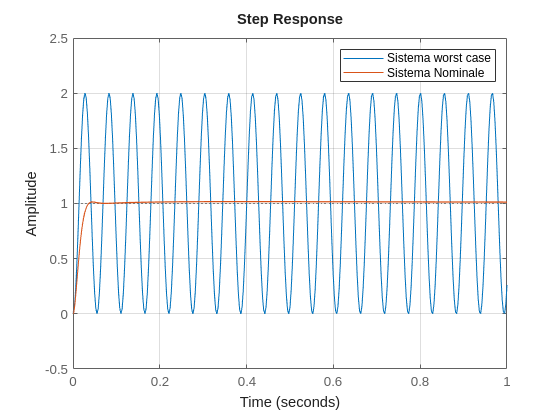


% xlim([0 10]);
% ylim([-2,2]) PER MOTIVI DIDDATTICI CHIEDERE A CAVALLO SE VUOLE CONTATTARE
% MATLAB E SCRIVERE UN ARTICOLO 
figure
step(CLwcu, CL, 1)
% step(CL,1)
grid on 
legend( 'Sistema worst case', 'Sistema Nominale')

if(isstable(Gwcu))
    disp('Il sistema wcu è: stabile')
else
    disp('Il sistema wcu è: Instabile')
end

Il sistema wcu è: Instabile


Il sistema, come previsto, si porta al limite di stabilità

#### Funzioni di Sensitività 

S_nom = minreal(feedback(1, G0_ss *Kinf));          % sensitivity

2 states removed.


T_nom = minreal(1 - S_nom);                        % complementary sensitivity

1 state removed.


Q_nom = minreal(Kinf * S_nom);            % control sens

6 states removed.



fprintf('||S||_inf = %.3g\n', norm(S_nom,Inf));

||S||_inf = 1.24


fprintf('||T||_inf = %.3g\n', norm(T_nom,Inf));

||T||_inf = 1.01


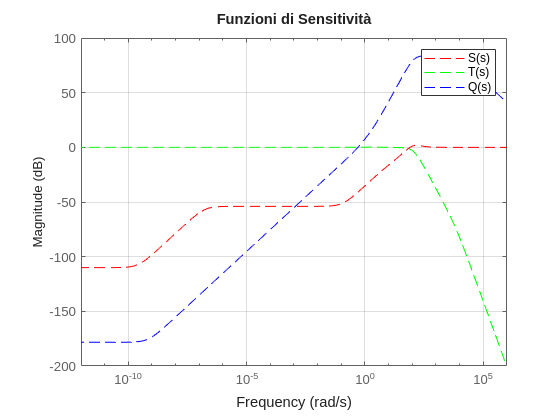

figure
% PLOT  
bpp = bodeplot(S_nom,'r--', T_nom, 'g--', Q_nom, 'b--');
bpp.PhaseVisible = "off";
bpp.Title.String = "Funzioni di Sensitività";
bpp.Responses(1).Name = "S(s) ";
bpp.Responses(2).Name = "T(s)";
bpp.Responses(3).Name = "Q(s)";
bpp.LegendVisible = "on";
grid on

norm(CL, 'inf')

ans = 1.0186

## Forma TITO P2 (`augw`) 

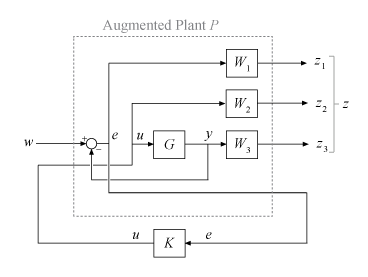

Si è scelto, per esperimento, di provare anche una nuova forma TITO, utilizzando il comando `augw` , che presenta una forma matriciale diversa da quella vista in precedenza. 

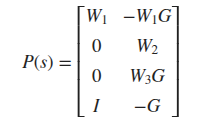

In questo caso: 

- $W_1$ per l'inseguimento del riferimento e la reiezione dei disturbi in bassa frequenza 

- $W_2$ per lo sforzo di controllo

- $W_3$ per la robustezza e l'attenuazione del rumore 

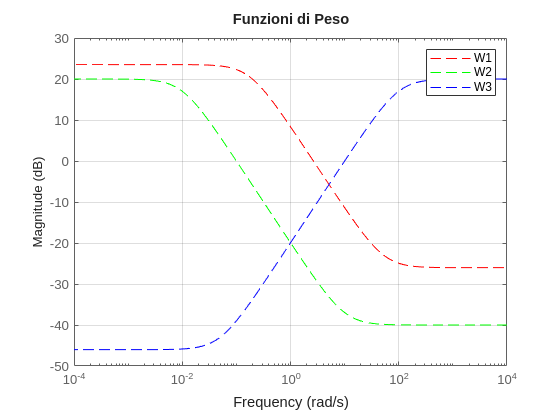

W1 = makeweight(15, [0.5 5], 0.05);   % peso su S (tracking)
W2 = makeweight(10,  [0.1 1], 0.01);   % peso su KS (sforzo controllo)
% W3 = makeweight(0.5,[  0.2], 0.02); % rumore e robust

% W1 = makeweight(10, [3 5], 0.05); 
% W2 = makeweight(2,  [3 1], 0.01); 
W3 = makeweight(.005, 10, 10); % 

% P2 
P2 = augw(G_ss, W1, W2, W3);
P2 = minreal(P2);

close all
figure
% PLOT PESI  
bw2 = bodeplot(W1,'r--', W2, 'g--', W3,'b--');
bw2.PhaseVisible = "off";
bw2.Title.String = "Funzioni di Peso";
bw2.Responses(1).Name = "W1 ";
bw2.Responses(2).Name = "W2";
bw2.Responses(3).Name = "W3";
bw2.LegendVisible = "on";
grid on

## Controllore $H_\infty$ (2)

Si progetta il nuovo controllore per la `P2 `

[Kinf2,Tzw2 ,gam] = hinfsyn(P2,1,1); % Hinf syn 
Kinf2 = minreal(Kinf2);
fprintf('gamma ottenuto: %.3f\n', gam);

gamma ottenuto: 0.942



% closed loop Nominale nuovo controllore 
CL0 = feedback(G0_tf*Kinf2,1);
CL_2 = minreal(feedback(G_ss * Kinf2, 1));
norm(CL_2,'inf')

ans = 1.2652


S_nom = minreal(feedback(1, CL_2));        % sensitivity
T_nom = minreal(1 - S_nom);                % complementary sensitivity
Q_nom = minreal(Kinf2 * S_nom);            % control sens
fprintf('||S||_inf=%.3f, ||T||_inf=%.3f, ||T_ur||_inf=%.3f\n', ...
    norm(S_nom,Inf), norm(T_nom,Inf), norm(Q_nom,Inf));

||S||_inf=1.142, ||T||_inf=0.569, ||T_ur||_inf=90.021


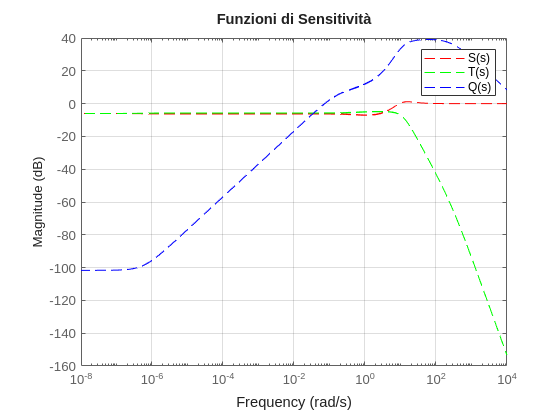


close all
% PLOT Sensitività 
bpp = bodeplot(S_nom,'r--', T_nom, 'g--', Q_nom, 'b--');
bpp.PhaseVisible = "off";
bpp.Title.String = "Funzioni di Sensitività";
bpp.Responses(1).Name = "S(s) ";
bpp.Responses(2).Name = "T(s)";
bpp.Responses(3).Name = "Q(s)";
bpp.LegendVisible = "on";
grid on

### Margini di stabilità robusta (`Kinf2`)

Si vanno a controllare i margini di stabilità robusta per il nuovo sistema ciclo chiuso `CL2,` col nuovo controllore `Kinf2` 

disp('Margini di stabilità robusta:  ')

Margini di stabilità robusta:  


opts = robOptions('VaryFrequency','on', 'Display','on');
[stabmarg,wcu,info] = robstab(CL_2, opts);

Computing bounds... Points completed: 62/62
Computing peak...  Percent completed: 100/100
System is robustly stable for the modeled uncertainty.
 -- It can tolerate up to 269% of the modeled uncertainty.
 -- There is a destabilizing perturbation amounting to 269% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 8.31 rad/seconds.



semilogx(info.Frequency,info.Bounds)
title('Margini di stabilità ')
ylabel('Margini')
xlabel('Frequenza')
legend('Lower bound','Upper bound')
xlim([.1 stabmarg.CriticalFrequency+100])

Anche in questo caso si ottengono **ottimi margini di stabilità robusta. **

Si controlla la **step response **del sistema incerto e si stima la sovraelongazione del sistema nominale per valutarne le performance (nominali) 

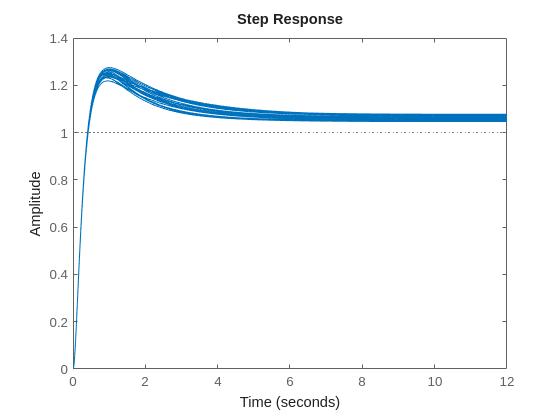

close all
step(CL_2);

[y_step, ~] = step(CL_2.NominalValue, tfin);

overshoot_nom = (max(y_step) - y_step(end)) / y_step(end) * 100; %  in Percentuale
fprintf('Overshoot nominale (%%) = %.2f\n', overshoot_nom);

Overshoot nominale (%) = 16.93



bodemag(CL_2)
grid on
title("Bode del sistema CL_2 (uss) ")


Con i pesi scelti si ottengono dei risultati peggiori rispetto al caso precedente, per quanto riguarda la sovraelongazione, il tempo di risposta, errore a regime. 

## Analisi di Stabilità robusta con $\mu -\textrm{Analysis}\;$ (1 e 2)

Si procede con lo studio della stabilità robusta attraverso la stima dell' `ssv `*(Structured Singular Value).*

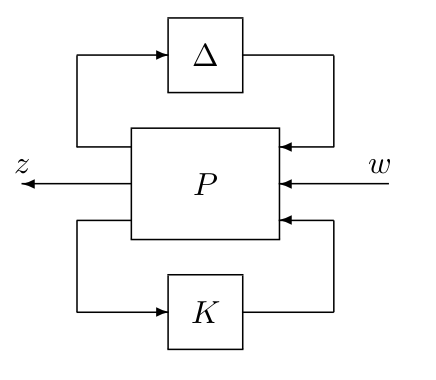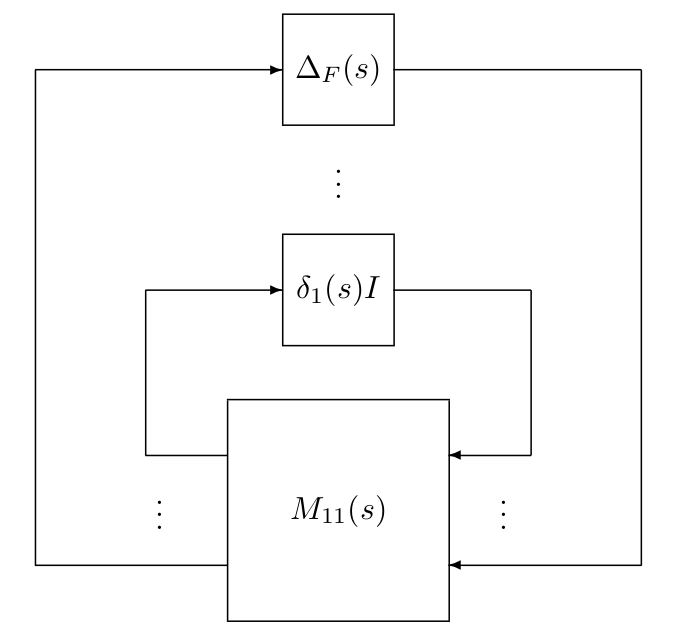

Attraverso il valor singolare strutturato, si controlla la stabilità robusta rispetto ad un intervallo di frequenze.

Si ha che, se $\mu \left(M\left(j\omega \right)\right)<1\;\forall \;\omega \;$, il sistema risulta robustamente stabile per le incertezze modellate, in particolare si procede con la stima del Lower Bound ed Upper bound di $\mu$

Si procede inizialmente con l'analisi per il sistema  `CL2,` con l'ausilio dei comandi: `lftdata, mussv`

% forse bisogna modificare di nuovo i pesi 

close all
[M2,Delta2,BlkStruct] = lftdata(CL_2);
% verificaCompl = norm(CL_2-lft(Delta,M),'inf'); 
szDelta2 = size(Delta2);
M11_2 = M2(1:szDelta2(2),1:szDelta2(1)); 
axislimit = [-1 3]; % Esponente Range di calcolo e visualizzazione 
% axislimit = [stabmarg.CriticalFrequency-1e-2 stabmarg.CriticalFrequency+1e3]; % Esponente Range di calcolo e visualizzazione 

omega = logspace(axislimit(1),axislimit(2),400);

M11_g2 = frd(M11_2,omega);
mubnds2 = mussv(M11_g2,BlkStruct,'s');
mumax = [max(mubnds2(1,1).ResponseData) max(mubnds2(1,2).ResponseData)]; % max di upper e lower bound di mu

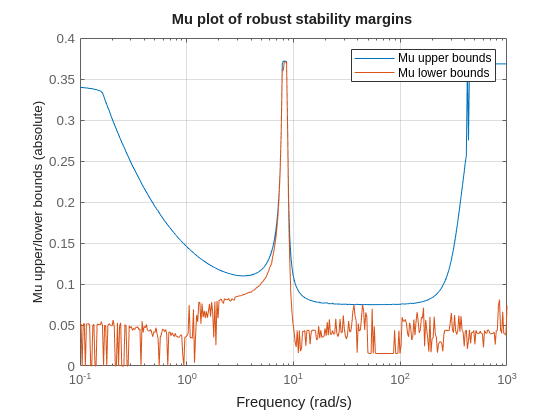


bp2 = bodeplot(mubnds2(1,1),mubnds2(1,2));
bp2.PhaseVisible = 'off';
bp2.MagnitudeUnit = 'abs';
bp2.XLimits = [10^axislimit(1),10^axislimit(2)];
bp2.XLabel.String = "Frequency";
bp2.YLabel.String(1) = "Mu upper/lower bounds";
bp2.Title.String = ("Mu plot of robust stability margins ");
legend("Mu upper bounds", "Mu lower bounds")
grid on



fprintf('Max Mu upper bound = %.3g\n Min Mu lower bound = %.3g\n', mumax(1), mumax(2));

Max Mu upper bound = 0.372
 Min Mu lower bound = 0.372


Si evince dal grafico che il valore del `ssv` rimane inferiore a 1, quindi garantendo la stabilità robusta (anche in questo caso) per le incertezze modellate. 

#### Analisi stabiltà Robusta CL (1)

Si procede ora con l'analisi di stabilità robusta, utilizzando lo stesso metodo cui sopra, per il sistema `CL`


close all
% P1 
[M1,Delta1,BlkStruct] = lftdata(CL);
% verificaCompl = norm(CL_2-lft(Delta,M),'inf'); 
szDelta1 = size(Delta1);
M11_1 = M1(1:szDelta1(2),1:szDelta1(1)); 
axislimit = [-1 3]; % Esponente Range di calcolo e visualizzazione 
% axislimit = [stabmarg.CriticalFrequency-1e-2 stabmarg.CriticalFrequency+1e3]; % Esponente Range di calcolo e visualizzazione 

omega = logspace(axislimit(1),axislimit(2),400);


M11_g1 = frd(M11_1,omega);
mubnds1 = mussv(M11_g1,BlkStruct,'s');
mumax = [max(mubnds1(1,1).ResponseData) max(mubnds1(1,2).ResponseData)]; % max di upper e lower bound di mu

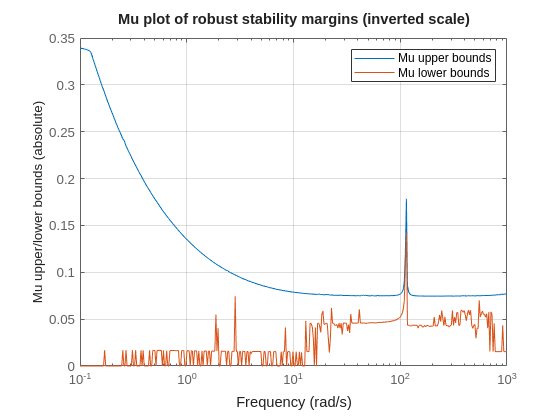


bp1 = bodeplot(mubnds1(1,1),mubnds1(1,2));
bp1.PhaseVisible = 'off';
bp1.MagnitudeUnit = 'abs';
bp1.XLimits = [10^axislimit(1),10^axislimit(2)];
bp1.XLabel.String = "Frequency";
bp1.YLabel.String(1) = "Mu upper/lower bounds";
bp1.Title.String = "Mu plot of robust stability margins (inverted scale)";
grid on;
legend("Mu upper bounds", "Mu lower bounds");


fprintf('Max Mu upper bound = %.3g\n', mumax(1));

Max Mu upper bound = 0.339


fprintf('Max Mu lower bound = %.3g\n', mumax(2));

Max Mu lower bound = 0.143


Anche nel caso di `CL1`, si ha che il valore del `ssv` rimane inferiore a 1, rispetto alle incertezze modellate 

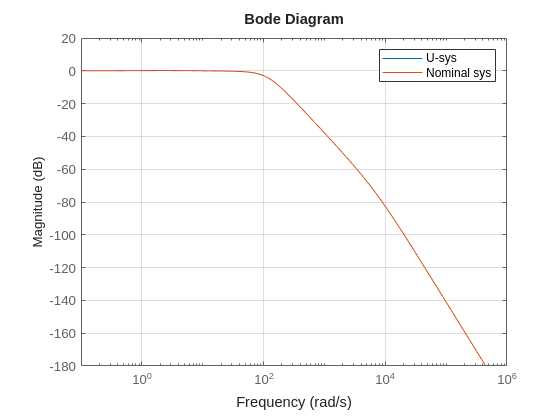

bodemag(CL, CL.NominalValue)
legend('U-sys', 'Nominal sys')
grid on

### **Analisi di prestazioni robuste (**`robgain`**)**

Dopo l'analisi di stabilità robusta, è stata condotta un’analisi di prestazioni robuste mediante la funzione `robgain`.

Questa funzione calcola i margini di performance robusta per un sisema incerto, le quali sono misurate sottoforma di massimo valor singolare, ed è relativo ad un livello di incertezza specificato (nel nostro caso 2).

Verranno analizzati i margini per entrambi i sistemi (`CL, CL2`)

[perfmarg1,wcu1, info1] = robgain(CL, 2, opts) 

Computing bounds... Points completed: 67/67
Computing peak...  Percent completed: 100/100
The performance level 2 is robust to the modeled uncertainty.
 -- The gain remains below 2 for up to 211% of the modeled uncertainty.
 -- There is a bad perturbation amounting to 271% of the modeled uncertainty.
 -- This perturbation causes a gain of 2 at the frequency 71.4 rad/seconds.


perfmarg1 = struct with fields:
           LowerBound: 2.1138
           UpperBound: 2.7078
    CriticalFrequency: 71.4026


wcu1 = struct with fields:
    a11_u: -0.3952
    a21_u: -4.9754
     b1_u: 9.3858


info1 = struct with fields:
                Model: 1
            Frequency: [69×1 double]
               Bounds: [69×2 double]
    WorstPerturbation: [69×1 struct]
          Sensitivity: [1×1 struct]


[perfmarg2,wcu2, info2] = robgain(CL_2, 2, opts) 

Computing bounds... Points completed: 62/62
Computing peak...  Percent completed: 100/100
The performance level 2 is robust to the modeled uncertainty.
 -- The gain remains below 2 for up to 258% of the modeled uncertainty.
 -- There is a bad perturbation amounting to 258% of the modeled uncertainty.
 -- This perturbation causes a gain of 2 at the frequency 3.73 rad/seconds.


perfmarg2 = struct with fields:
           LowerBound: 2.5772
           UpperBound: 2.5821
    CriticalFrequency: 3.7308


wcu2 = struct with fields:
    a11_u: -0.0200
    a21_u: -4.9712
     b1_u: 0.5382


info2 = struct with fields:
                Model: 1
            Frequency: [64×1 double]
               Bounds: [64×2 double]
    WorstPerturbation: [64×1 struct]
          Sensitivity: [1×1 struct]



CLmax = usubs(CL,wcu1);
getPeakGain(CLmax,1e-6)

ans = 2.0004

Examine the disturbance rejection of the system with these values.

close all
subplot(1, 2, 1)
grid on
step(CL.NominalValue,CLmax)
title("Step response WCU 1")
legend('Nominal','Peak Gain = 2')

CLmax2 = usubs(CL_2,wcu2);
getPeakGain(CLmax2,1e-6)

ans = 1.9999

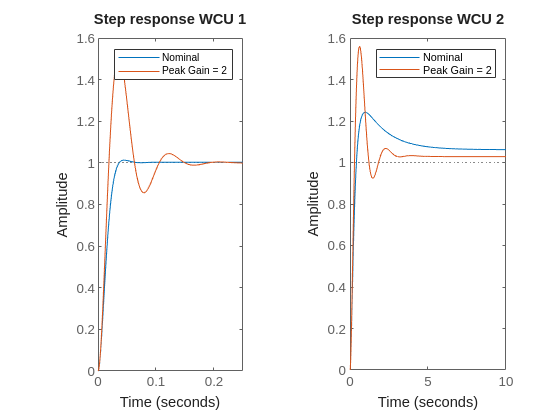

subplot(1, 2, 2)
grid on
step(CL_2.NominalValue,CLmax2)
title("Step response WCU 2")
legend('Nominal','Peak Gain = 2')

### Tentativo di $\mu$-synthesis (extra) 

Questo controllore viene sviluppato con una D-K iteration, viene progettato, per ogni iterazione un controllore $H_\infty$, restringendo sempre di più (utilizzando `uscale`) il range di incertezze per le quali valutare la robustezza con il valore singolare strutturato

% TEST NEW
% mu-sintesi 

[Kmu, rp ] = musyn(P2, 1,1);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1            20.7        3.719         3.73            12
    2           1.112        1.109        1.116            12
    3           1.024        1.023        1.032            18
    4           1.018        1.016        1.025            14
    5           1.021        1.019        1.028            14

Best achieved robust performance: 1.02



Kmu=minreal(Kmu);

3 states removed.


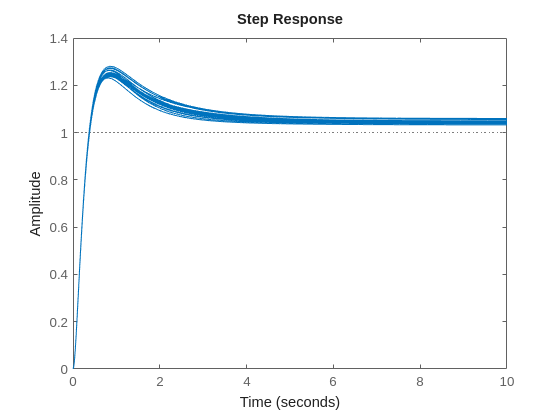


CLmu = feedback(G_ss*(Kmu),1);
CLmu_nom=CLmu.NominalValue;
close all
step(CLmu)

[y_step,t] = step(CLmu_nom,50);
overshoot_nom = (max(y_step)-y_step(end))/y_step(end)*100;
fprintf('Overshoot nominale = %.2f %%\n', overshoot_nom);

Overshoot nominale = 19.57 %



% Robust stability
opts = robOptions('VaryFrequency','on','Display','on');
[stabmarg_mu,wcu_mu,info_mu] = robstab(CLmu, opts);

Computing bounds... Points completed: 52/52
Computing peak...  Percent completed: 100/100
System is robustly stable for the modeled uncertainty.
 -- It can tolerate up to 269% of the modeled uncertainty.
 -- There is a destabilizing perturbation amounting to 269% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 8.29 rad/seconds.


fprintf('Robust Stability Margin LowerBound = %.2f (%.0f%% tolleranza)\n',...
    stabmarg_mu.LowerBound, (stabmarg_mu.LowerBound-1)*100);

Robust Stability Margin LowerBound = 2.69 (169% tolleranza)



% µ-analysis (Structured Singular Value)
[Mmu,Delta_mu,BlkStruct_mu] = lftdata(CLmu);
omega = logspace(-2,3,200);
M11_mu = Mmu(1:size(Delta_mu,2),1:size(Delta_mu,1));
mubnds = mussv(frd(M11_mu,omega),BlkStruct_mu,'s');
mu_upper = max(mubnds(1,1).ResponseData);
mu_lower = max(mubnds(1,2).ResponseData);
fprintf('Max µ upper bound = %.3f\n', mu_upper);

Max µ upper bound = 0.372


fprintf('Max µ lower bound = %.3f\n', mu_lower);

Max µ lower bound = 0.371



% Robust performance
[perfmarg_mu,wcu_mu,~] = robgain(CLmu,2,opts);

Computing bounds... Points completed: 52/52
Computing peak...  Percent completed: 100/100
The performance level 2 is robust to the modeled uncertainty.
 -- The gain remains below 2 for up to 257% of the modeled uncertainty.
 -- There is a bad perturbation amounting to 258% of the modeled uncertainty.
 -- This perturbation causes a gain of 2 at the frequency 3.85 rad/seconds.


fprintf('Robust Performance Margin Upepr bound (livello=2) = %.3f\n', perfmarg_mu.UpperBound);

Robust Performance Margin Upepr bound (livello=2) = 2.575


Caso perturbazioni con peak 2 

CLmumax = usubs(CLmu,wcu_mu);
getPeakGain(CLmumax,1e-6)

ans = 1.9999

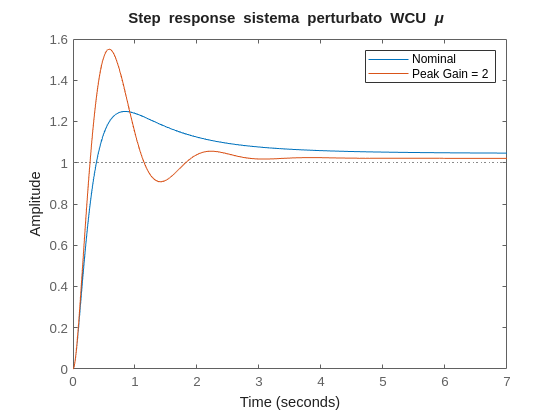


close all
figure
grid on
step(CLmu.NominalValue,CLmumax)
title("Step response sistema perturbato WCU \mu ")
legend('Nominal','Peak Gain = 2')

#### Riduzione Ordine Controllore ( $\mu \;$) 

È stata fatta una prova per ridurre l'ordine del controllore $\mu \;$al terzo ordine, visto l'ordine elevato del precedente (22° ordine)

C0 = tunableSS('C0',3,1,1);
CL0 = lft(P2,C0);
[CLmu2,CLmuperf,info] = musyn(CL0);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1            20.7         9.43        9.607            16
    2            1.09        1.049         1.06            12
    3           1.033        1.029        1.035            12
    4           1.033        1.027        1.033            12
    5           1.033        1.026        1.033            12

Best achieved robust performance: 1.03



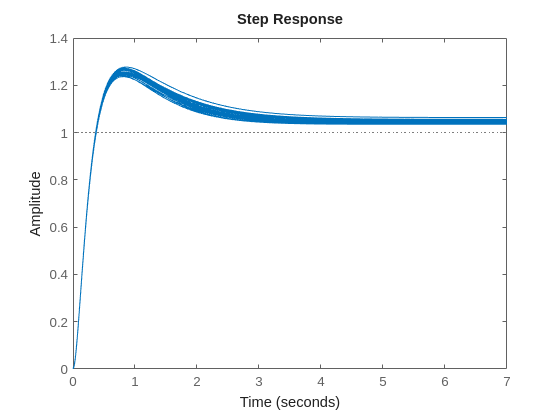

Kmu2 = getBlockValue(CLmu2, 'C0');

CLmuReduced = feedback(G_ss*Kmu2,1);  % ciclo chiuso nominale
step(CLmuReduced)

%  Analisi Robustezza

[stabmarg_mu,~,info_mu] = robstab(CLmuReduced, opts);

Computing bounds... Points completed: 47/47
Computing peak...  Percent completed: 100/100
System is robustly stable for the modeled uncertainty.
 -- It can tolerate up to 268% of the modeled uncertainty.
 -- There is a destabilizing perturbation amounting to 269% of the modeled uncertainty.
 -- This perturbation causes an instability at the frequency 8.34 rad/seconds.


fprintf('Robust Stability Margin LowerBound = %.2f (%.0f%% tolleranza)\n',...
    stabmarg_mu.LowerBound, (stabmarg_mu.LowerBound-1)*100);

Robust Stability Margin LowerBound = 2.68 (168% tolleranza)



% µ-analysis (Structured Singular Value)
[Mmu,Delta_mu,BlkStruct_mu] = lftdata(CLmuReduced);
omega = logspace(-2,3,200);
M11_mu = Mmu(1:size(Delta_mu,2),1:size(Delta_mu,1));
mubnds = mussv(frd(M11_mu,omega),BlkStruct_mu,'s');
mu_upper = max(mubnds(1,1).ResponseData);
mu_lower = max(mubnds(1,2).ResponseData);
fprintf('Max µ upper bound = %.3f\n', mu_upper);

Max µ upper bound = 0.372


fprintf('Max µ lower bound = %.3f\n', mu_lower);

Max µ lower bound = 0.371



% Robust performance
[perfmarg_mu,wcu_mu,~] = robgain(CLmuReduced,2,opts);

Computing bounds... Points completed: 47/47
Computing peak...  Percent completed: 100/100
The performance level 2 is robust to the modeled uncertainty.
 -- The gain remains below 2 for up to 257% of the modeled uncertainty.
 -- There is a bad perturbation amounting to 257% of the modeled uncertainty.
 -- This perturbation causes a gain of 2 at the frequency 3.83 rad/seconds.


fprintf('Robust Performance Margin Upepr bound (livello=2) = %.3f\n', perfmarg_mu.UpperBound);

Robust Performance Margin Upepr bound (livello=2) = 2.572



CLmumax = usubs(CLmuReduced,wcu_mu);
getPeakGain(CLmumax,1e-6)

ans = 2.0000

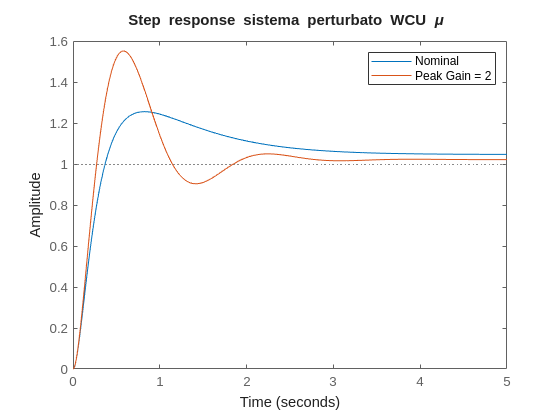


close all
figure
grid on
step(CLmuReduced.NominalValue,CLmumax)
title("Step response sistema perturbato WCU \mu ")
legend('Nominal','Peak Gain = 2')

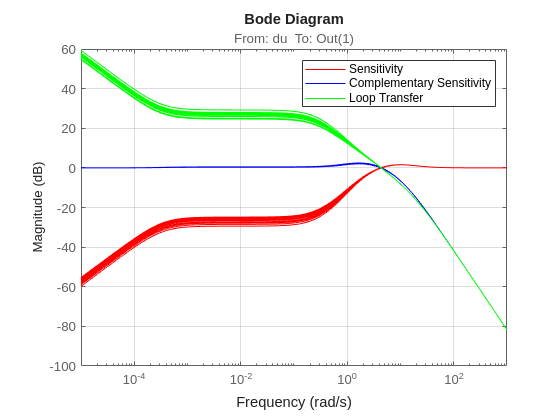


loops = loopsens(G_ss,Kmu2); 
bodemag(loops.Si,'r',loops.Ti,'b',loops.Li,'g')
legend('Sensitivity','Complementary Sensitivity','Loop Transfer')
grid on

Riferimenti: 

- MathWorks, Inc. , "*Robust Control Toolbox User's Guide" (* [https://it.mathworks.com/help/pdf_doc/robust/robust_ug.pdf](https://it.mathworks.com/help/pdf_doc/robust/robust_ug.pdf))

- Examples: "[Robust Control of Active Suspension](https://it.mathworks.com/help/robust/gs/active-suspension-control-design.html?searchHighlight=ActiveSuspensionExample&s_tid=srchtitle_support_results_4_ActiveSuspensionExample)" , "[Robust Stability, Robust Performance, and Mu Analysis](https://it.mathworks.com/help/robust/ug/robust-stability-robust-performance-and-mu-analysis.html?searchHighlight=Robust+Stability%2C+Robust+Performance%2C+and+Mu+Analysis&s_tid=srchtitle_support_results_1_Robust+Stability%252C+Robust+Performance%252C+and+Mu+Analysis)". 

- . Essentials of robust control: Kemin Zhou, John C. Doyle Prentice-Hall, Englewood Cliffs, NJ, 1998, ISBN: 0-13-790874-1.. Automatica. 38. 910-912.